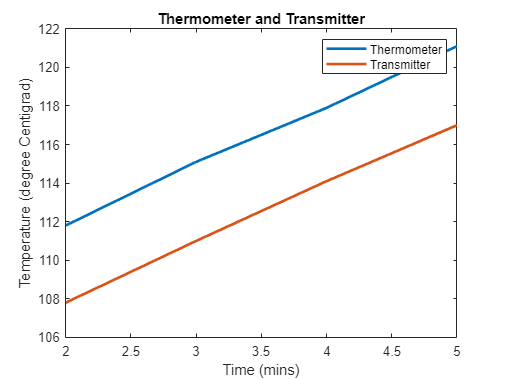

clc
clear
T = [0 100 200 400];
T_m = [4 8.1 11.9 16.1 20];

t=[2 3 4 5];
Thermo = [111.8 115.1 117.9 121.1];
Trans = [107.8 111 114.1 117];

plot(t,Thermo,'LineWidth',2)
hold on
plot(t,Trans,'LineWidth',2)
hold off
title("Thermometer and Transmitter")
ylabel("Temperature (degree Centigrad)")
legend("Thermometer","Transmitter")
xlabel("Time (mins)")

x1 = interp1(Thermo,t,112)

x1 = 2.0606

x2 = interp1(Trans,t,112)

x2 = 3.3226

del_x = x2-x1

del_x = 1.2620

del_x*60

ans = 75.7185


% for linear valves
p=5

p = 5

l = @(q) ((q/188.5).*((35-0.00075*q.*q)/1.11).^(-0.5));
[Y,X]=fplot(l,[0 300]);

plot(X,Y,LineWidth=2)
xlim([0 1]);
grid on
hold on
% for equal %
l = @(q) ( 1 + (log((q/188.5).*((35-0.00075*q.*q)/1.11).^(-0.5)))/log(10));
[Y,X]=fplot(l,[0 300]);

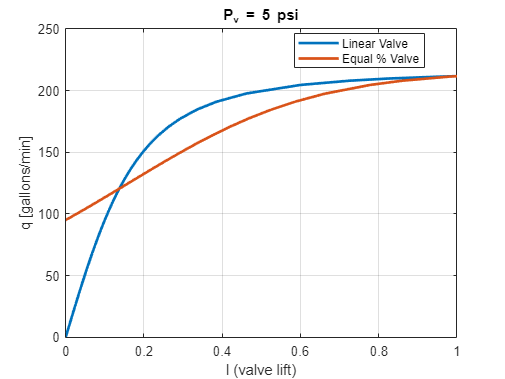

plot(X,Y,LineWidth=2)
xlim([0 1]);
legend('Linear Valve', 'Equal % Valve',Location='best')
title('P_v = 5 psi')
hold off
xlabel('l (valve lift)')
ylabel('q [gallons/min]')


% for linear valves
p=30

p = 30

l = @(q) ((q/76.94).*((60-0.00075*q.*q)/1.11).^(-0.5));
[Y,X]=fplot(l,[0 300]);

plot(X,Y,LineWidth=2)
xlim([0 1]);
grid on
hold on
% for equal %
l = @(q) ( 1 + (log((q/76.94).*((60-0.00075*q.*q)/1.11).^(-0.5)))/log(10));
[Y,X]=fplot(l,[0 300]);

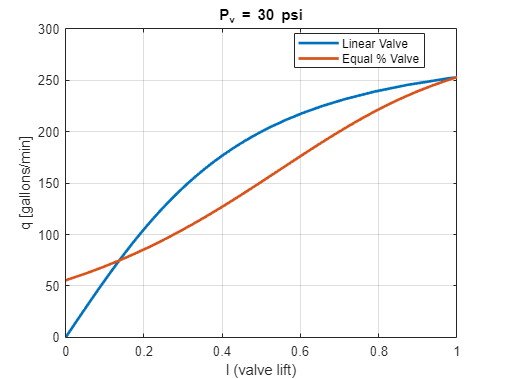

plot(X,Y,LineWidth=2)
xlim([0 1]);
legend('Linear Valve', 'Equal % Valve',Location='best')
title('P_v = 30 psi')
hold off
xlabel('l (valve lift)')
ylabel('q [gallons/min]')


% for linear valves
p=90

p = 90

l = @(q) ((q/44.42).*((120-0.00075*q.*q)/1.11).^(-0.5));
[Y,X]=fplot(l,[0 300]);

plot(X,Y,LineWidth=2)
xlim([0 1]);
grid on
hold on
% for equal %
l = @(q) ( 1 + (log((q/44.42).*((120-0.00075*q.*q)/1.11).^(-0.5)))/log(10));
[Y,X]=fplot(l,[0 300]);

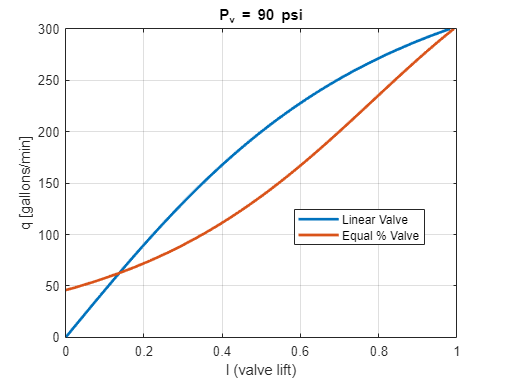

plot(X,Y,LineWidth=2)
xlim([0 1]);
legend('Linear Valve', 'Equal % Valve',Location='best')
title('P_v = 90 psi')
hold off
xlabel('l (valve lift)')
ylabel('q [gallons/min]')